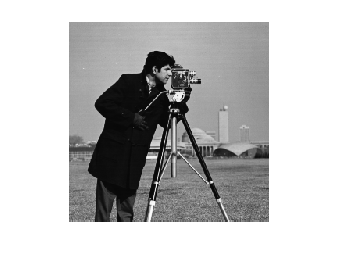

img = imread('Important_files/cameraman.tif');
imshow(img)

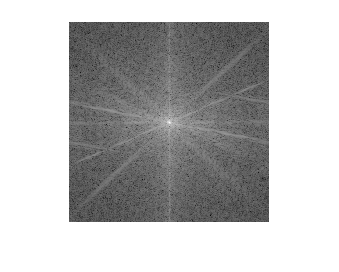

dft = fft2(img);
shifted_dft = fftshift(dft);
dft_mag = abs(shifted_dft);
dft_phase = angle(shifted_dft);

imshow(log(dft_mag)+1,[])

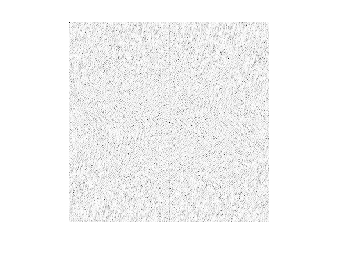

imshow(real(log(dft_phase)),[])

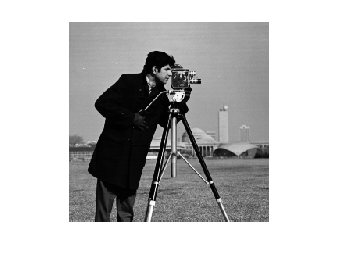

reconstructed = ifft2(dft);
imshow(reconstructed, [])

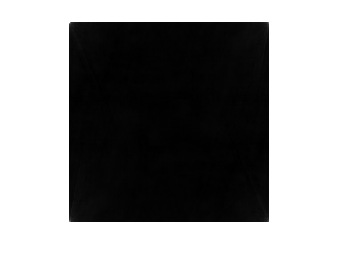

rec_amp = ifft2(abs(dft).*exp(1j));
imshow(real(rec_amp), [])

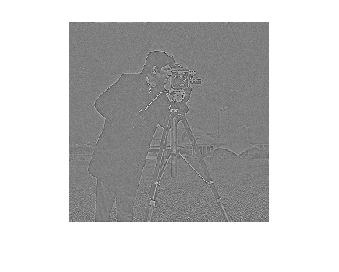

rec_phase = ifft2(exp(1j*angle(dft)));
imshow(real(rec_phase), [])

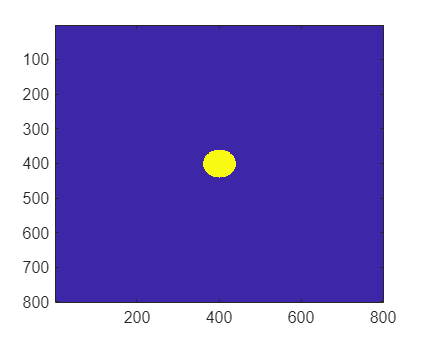

[X,Y] = meshgrid(-400:400);
radius = 40;
A = (sqrt(X.^2 + Y.^2) <= radius);
B = (X <= radius & Y <= radius & X >= -radius & Y >= -radius);

imagesc(A)

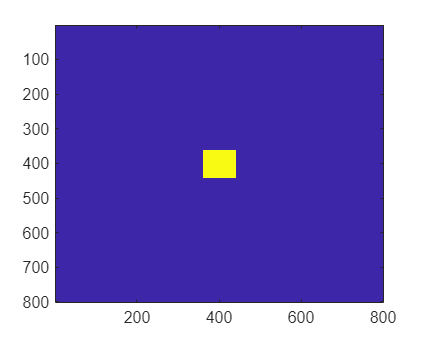

imagesc(B)

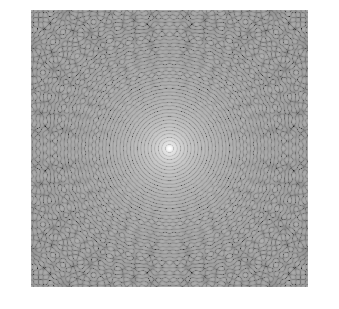

dft_circ = fft2(A);
dft_mag_circ = abs(fftshift(dft_circ));

imshow(log(dft_mag_circ)+1,[])

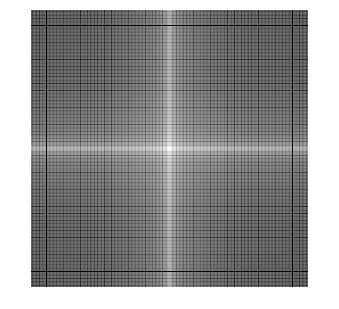

dft_sq = fft2(B);
dft_mag_sq = abs(fftshift(dft_sq));

imshow(log(dft_mag_sq)+1,[])

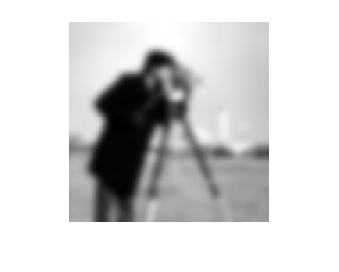

kernel = fspecial('gaussian',256,5);
filtered = imfilter(img, kernel, 'replicate');
imshow(filtered, [])

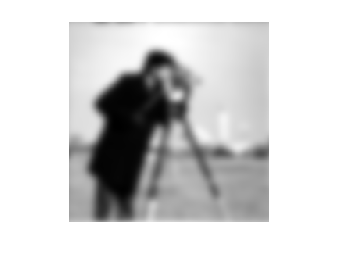


filtered_cool = fftshift(ifft2((fft2(kernel) .* fft2(img))));
imshow(real(filtered_cool), [])